## Load data

cd 'G:\My Drive\PhD_Research\BSF_Thesis\ModernAndSurfaceProcesses\Analyses\ModProcAnalyses\Figures\Figure6DiurnalFluxTemporal'
cd data\input

#### Weather Data

load('Bflat30min.mat')

#### Water Level

% load('BLM93_AirPresCor.mat')
load("BLM93C.mat")
BLM93C.WaterLevelBelowSurface_m(21638) = NaN; %make sure there is a gap in the plot

cd ../output/

## BLM 93C DTW and change in air pressure

BLM93C = removevars(BLM93C, 'WellID_BLM');
BLM93Cdaily = retime(BLM93C, "daily", 'mean');

BLM93Chourly = retime(BLM93C, 'hourly', @mean);
Bflat30minhourly = retime(Bflat30min, 'hourly', @mean);
BLM93Chourly = outerjoin(BLM93Chourly, Bflat30minhourly,'Type','left');

BLM93CdailyMin = retime(BLM93Chourly, "daily","min");
BLM93CdailyMax = retime(BLM93Chourly, "daily","max");
BLM93CdailySum = retime(BLM93Chourly, "daily","sum");
BLM93CdailyChange = join(BLM93CdailyMin, BLM93CdailyMax);

BLM93CdailyChange.DTW_range = BLM93CdailyChange.WaterLevelBelowSurface_m_BLM93CdailyMax - BLM93CdailyChange.WaterLevelBelowSurface_m_BLM93CdailyMin;
BLM93CdailyChange.Temp_range = BLM93CdailyChange.AirTemp1_C_BLM93CdailyMax - BLM93CdailyChange.AirTemp1_C_BLM93CdailyMin;
BLM93CdailyChange.AirPRessure_range = BLM93CdailyChange.Pressure_kPa_BLM93CdailyMax - BLM93CdailyChange.Pressure_kPa_BLM93CdailyMin;

BLM93CdailyChange.DTW_rangeSmoothed = smoothdata(BLM93CdailyChange.DTW_range,...
    'movmedian','SmoothingFactor',0.5,...
    'SamplePoints',BLM93CdailyChange.Date_Time_MDT);

BLM93CdailyChange.Temp_rangeSmoothed = smoothdata(BLM93CdailyChange.Temp_range,...
    'movmean','SmoothingFactor',0.5,...
    'SamplePoints',BLM93CdailyChange.Date_Time_MDT);

BLM93CdailyChange.AirTemp1_C_BLM93CdailyMaxSmoothed = smoothdata(BLM93CdailyChange.AirTemp1_C_BLM93CdailyMax,...
    'movmean','SmoothingFactor',0.12,...
    'SamplePoints',BLM93CdailyChange.Date_Time_MDT);

# Figure: Controls on diurnal water level

figure
tiledlayout (5,2)
sz = 5;

BLM93CdailyChange.DTW_rangeSmoothed(227:268) = NaN;

nexttile ([1,2])
hold on
scatter(BLM93CdailyChange.Date_Time_MDT, BLM93CdailyChange.DTW_range*100,sz, [0 0.4470 0.7410], 'DisplayName','measurements')
plot(BLM93CdailyChange.Date_Time_MDT, BLM93CdailyChange.DTW_rangeSmoothed*100,':','color', [0 0.4470 0.7410],'linewidth', 2, 'DisplayName','smoothed fit')
ylabel('0.8 m well \Delta water depth (cm)')
ylim([0,7])
xlim(BLM93CdailyChange.Date_Time_MDT([1 , end]))
% scatter(BLM93CdailyChange.Date_Time_MDT, BLM93CdailyChange.AirPRessure_range)
xticklabels({})
legend('location', 'eastoutside')

#### BLM93C air temp

nexttile ([1,2])
yyaxis right
hold on
scatter(BLM93CdailyChange.Date_Time_MDT, BLM93CdailyChange.SoilTemp_C_BLM93CdailyMax - BLM93CdailyChange.SoilTemp_C_BLM93CdailyMin,sz, 'diamond', "filled",'DisplayName','measurements')
ylabel('\Delta soil temp. (^oC)')
ylim([0,8.5]) 
yyaxis left
scatter(BLM93CdailyChange.Date_Time_MDT, BLM93CdailyChange.SoilTemp_C_BLM93CdailyMax,sz)
% plot(BLM93CdailyChange.Date_Time_MDT, BLM93CdailyChange.AirTemp1_C_BLM93CdailyMaxSmoothed,':','linewidth', 2)
ylabel('max. soil temp. (^oC)')
xlim(BLM93CdailyChange.Date_Time_MDT([1 , end]))
xticklabels({})
legend('location', 'eastoutside')

#### BLM93C water level, PPT

nexttile ([1,2])
hold on

yyaxis left
plot(BLM93C.Date_Time_MDT, -BLM93C.WaterLevelBelowSurface_m*100,'-','linewidth', 1.0,'DisplayName','water depth')
% plot(BLM93Cdaily.Date_Time_MDT, -BLM93Cdaily.WaterLevelBelowSurface_m*100,'-','linewidth', 1.0,'DisplayName','water depth')
xlim(BLM93CdailyChange.Date_Time_MDT([1 , end]))
ylabel('water depth (cm)')
yline(0., 'HandleVisibility','off')
ylim([-20,6])

yyaxis right
bar(BLM93CdailySum.Date_Time_MDT, BLM93CdailySum.PPT_mm,1, 'displayname', 'PPT') %,'HandleVisibility','off')
ylabel('PPT (mm)')
ylim([0, 12.5])

legend('location', 'eastoutside')

### BLM93C max soil and DTW range

nexttile ([1,1])
hold on 

scatter(BLM93CdailyChange.SoilTemp_C_BLM93CdailyMax, BLM93CdailyChange.DTW_range*100, sz, [0 0.4470 0.7410])
% scatter(BLM93CdailyChange.AirTemp1_C_BLM93CdailyMax,BLM93CdailyChange.DTW_range, 2)
%Max Soil temp is the better predictor of delta water level than max air temperature
ylabel('0.8 m well \Delta water depth (cm)')
xlabel('max soil temp (^oC)')
%  legend('location', 'northwest')
xlim([-3,37])
ylim([0,7])

#### Delta water depth vs. average water depth

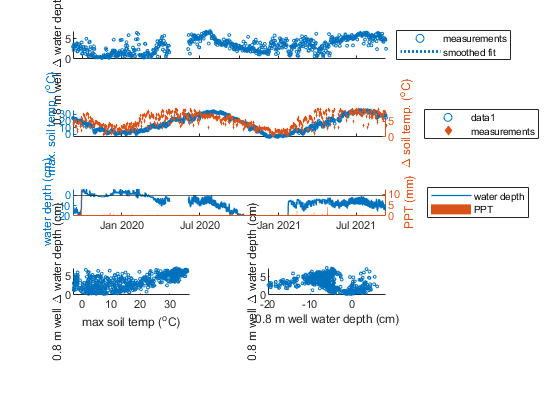

nexttile ([1,1])
scatter(-100*(BLM93CdailyChange.WaterLevelBelowSurface_m_BLM93CdailyMax+BLM93CdailyChange.WaterLevelBelowSurface_m_BLM93CdailyMin)/2, BLM93CdailyChange.DTW_range*100,sz, [0 0.4470 0.7410], 'DisplayName','measurements')
xlabel('0.8 m well water depth (cm)')
ylabel('0.8 m well \Delta water depth (cm)')
ylim([0,7.5])
xlim([-20,8])

print('BLM93CWaterDailyChange', '-fillpage','-dpdf') %'-bestfit' -fillpage